# SVM (Linear)

## Initialization (Dataset: LinearSeperableNoisy.csv)

data=csvread('LinearSeperableNoisy.csv');

- **Number of Data Points**

disp(length(data))

   400



- **Z-score Normalization**

data(:,1:end-1)=zscore(data(:,1:end-1));

- **Cross Validation**

[train,test] = holdout(data,80);

% Test set
Xtest=test(:,1:end-1);Ytest=test(:,end);

% Traing set
X=train(:,1:end-1);Y=train(:,end);

- **Visulaization of data**

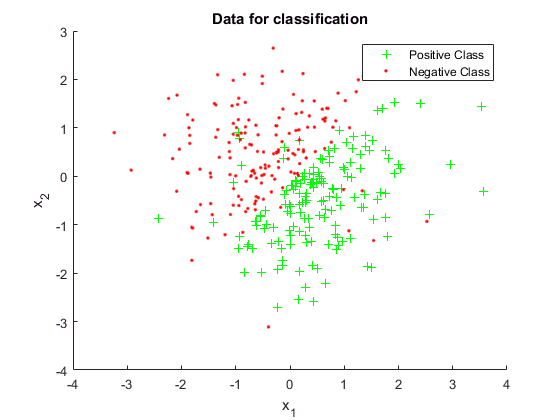

figure
hold on
scatter(X(Y==1,1),X(Y==1,2),'+g')
scatter(X(Y==-1,1),X(Y==-1,2),'.r')
xlabel('{x_1}')
ylabel('{x_2}')
legend('Positive Class','Negative Class')
title('Data for classification')
hold off

## Applying Gradient Ascent with linear Kernel

fm_=[];
for c=[0.1,1,2,5,7,10]
     
     % alpha
     alpha = grad_ascent(X,Y,c);
     
     % Possible support vectors
     Xs=X(alpha>0,:); Ys=Y(alpha>0);
     
     % weights
     W=(alpha(alpha>0).*Ys)'*Xs;
     
     % bias
     bias=mean(Ys-(Xs*W'));
     
     % f~ (Predicted labels)
     f=sign(Xtest*W'+bias);
     
     % confusion matrix
     fm= confusion_mat(Ytest,f);
     fm_=[fm_; c fm];    
end

total_iterations = 61

total_iterations = 353

total_iterations = 371

total_iterations = 4601

total_iterations = 6509

total_iterations = 8191

## Regularization parameter, C 'optimal'  

After Cross-Validation, Optimal 'c' value- Yeilding Best Performance (F-measure)

[max_fm, indx]=max(fm_(:,2));
c_optimal=fm_(indx,1)

c_optimal = 1

## Final Model

- ***Alpha***

alpha = grad_ascent(X,Y,c_optimal);

total_iterations = 353

Xs=X(alpha>0,:); Ys=Y(alpha>0);
Support_vectors=size(Xs,1)

Support_vectors = 114

- ***Weights***

W=(alpha(alpha>0).*Ys)'*Xs

W =     1.8826   -1.7329


- ***Bias***

bias=mean(Ys-(Xs*W'))    

bias = -0.1627

- ***f~ (Predicted labels)***


f=sign(Xtest*W'+bias);

- ***Performace Measure***

[F_measure, Accuracy] = confusion_mat(Ytest,f)

F_measure = 0.9367

Accuracy = 0.9375

## Slack Variables, ζ

**Remark**: Number of Support Vectors and non-zero ζ should be nearly same

ft=X*W'+bias;
zeta=max(0,1-Y.*ft);
Non_Zero_Zeta=sum(zeta~=0)

Non_Zero_Zeta = 110

Support_vectors

Support_vectors = 114

## Plotting the Hyperplane

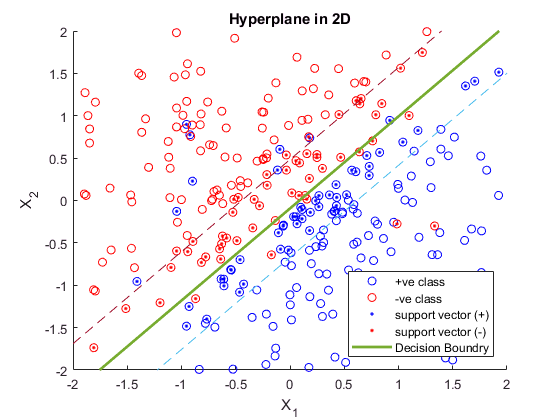

figure
hold on

scatter(X(Y==1,1),X(Y==1,2),'b')
scatter(X(Y==-1,1),X(Y==-1,2),'r')
scatter(Xs(Ys==1,1),Xs(Ys==1,2),'.b')
scatter(Xs(Ys==-1,1),Xs(Ys==-1,2),'.r')

syms x
fn=vpa((-bias-W(1)*x)/W(2),4);
fplot(fn,'Linewidth',2);
fn1=vpa((1-bias-W(1)*x)/W(2),4);
fplot(fn1,'--');
fn2=vpa((-1-bias-W(1)*x)/W(2),4);
fplot(fn2,'--');

axis([-2 2 -2 2])
xlabel('X_1')
ylabel('X_2')
title('Hyperplane in 2D')
legend('+ve class','-ve class','support vector (+)','support vector (-)','Decision Boundry','Location','southeast')
hold off

## Dual Value

Ker=X*X';
dual=(alpha)'*ones(size(X,1),1)-0.5*(alpha.*Y)'*Ker*(alpha.*Y)

dual = 110.2533

## Primal Value

primal=c_optimal*(zeta'*ones(size(X,1),1))+ norm(W,2)^2

primal = 114.6770

## Duality Gap

dualityGap= dual - primal

dualityGap = -4.4237

## Decision Boundry in Input Space

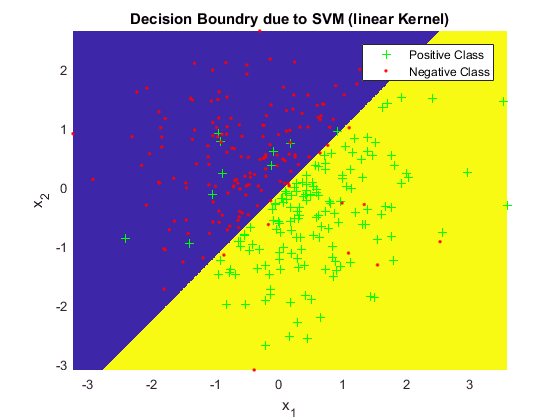

[x1 x2]=meshgrid(min(X(:,1)):0.005:max(X(:,1)),min(X(:,2)):0.005:max(X(:,2)));
Xn=[reshape(x1,1,size(x1,2)*size(x1,1))' reshape(x2,1,size(x2,2)*size(x2,1))'];

yn=sign(Xn*W'+bias);
Yn=reshape(yn,size(x1));

DecisionBoundry( X,Y,Yn )
title('Decision Boundry due to SVM (linear Kernel)')

% created by Bhartendu, Machine Learning & Computing 

[Bhartendu, Machine Learning & Computing, Mathworks File Exchange](https://in.mathworks.com/matlabcentral/profile/authors/10083740-bhartendu)